%% Optimization problem

% Clear previous data, close all figures, and reset command window
clear;
clc;
close all;

% === Energy function ===
% This function calculates how much energy a solar panel produces
% based on two inputs:
% - theta: the tilt angle of the panel (in degrees)
% - r: the aspect ratio (shape) of the panel
% The formula models how these two factors affect energy output.
function E = energyFun(x)
    theta = x(1);     % first variable is tilt angle
    r = x(2);         % second variable is aspect ratio
    % Energy is based on cosine of angle differences and shape efficiency
    E = 2 * cosd(theta - 30) * (1000 * cosd(theta - 45)) * exp(-0.1 * (r - 1)^2);
end

% 1. Create the optimization problem
% We're telling MATLAB: "We want to MAXIMIZE something."
% That "something" will be energy.
prob = optimproblem('ObjectiveSense','maximize');

% 2. Define the variables we can change in the problem
% These are the values MATLAB will try to optimize:
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4
theta = optimvar('theta','LowerBound',0,'UpperBound',90);
r = optimvar('r','LowerBound',0.5,'UpperBound',4);

% 3. Turn our energy function into something MATLAB can work with
% This step wraps our energy function so MATLAB can plug in different
% theta and r values while solving the problem.
x = [theta; r];  % Put both variables into a vector
Eexpr = fcn2optimexpr(@energyFun, x);  % Convert our function into an expression

% 4. Tell MATLAB what we want to maximize
% We set our energy formula as the "objective" of the problem
% (this is what we want the solver to maximize)
prob.Objective = Eexpr;

% 5. Give MATLAB a starting point to begin the search
% Optimization needs a guess to start from:
x0.theta = 30;  % Start searching from a tilt angle of 30 degrees
x0.r = 1;       % Start searching from an aspect ratio of 1

% Now solve the problem!
[sol, fval] = solve(prob, x0);


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Print the results to the screen
fprintf('Optimal Tilt Angle: %.2f deg\n', sol.theta);

Optimal Tilt Angle: 37.50 deg


fprintf('Optimal Aspect Ratio: %.2f\n', sol.r);

Optimal Aspect Ratio: 1.00


fprintf('Maximum Energy Output: %.2f units\n', fval);

Maximum Energy Output: 1965.93 units


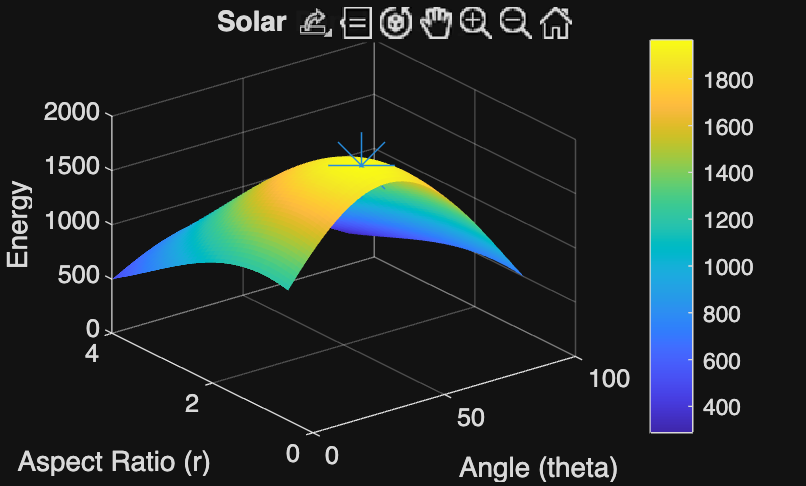



% 6. graph

% make a bunch of points for the x and y axis 
% the step for the angle is 1, the step for ratio is 0.1
[theta_grid, r_grid] = meshgrid(0:1:90, 0.5:0.1:4);

% now calculate the energy for every single point on my grid
E_grid = (2 * cosd(theta_grid - 30) .* (1000 * cosd(theta_grid - 45)) .* exp(-0.1 * (r_grid - 1).^2));

% draw the 3d graph
surf(theta_grid, r_grid, E_grid, 'EdgeColor', 'none');

% label everything
title('Solar Panel Energy');
xlabel('Angle (theta)');
ylabel('Aspect Ratio (r)');
zlabel('Energy');
colorbar;

% put a star on the plot to show where the most optimal point is
hold on;
plot3(sol.theta, sol.r, fval, '*', 'MarkerSize', 25);